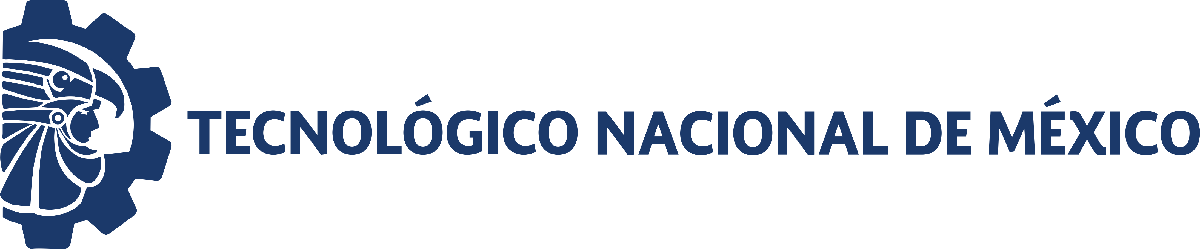                                 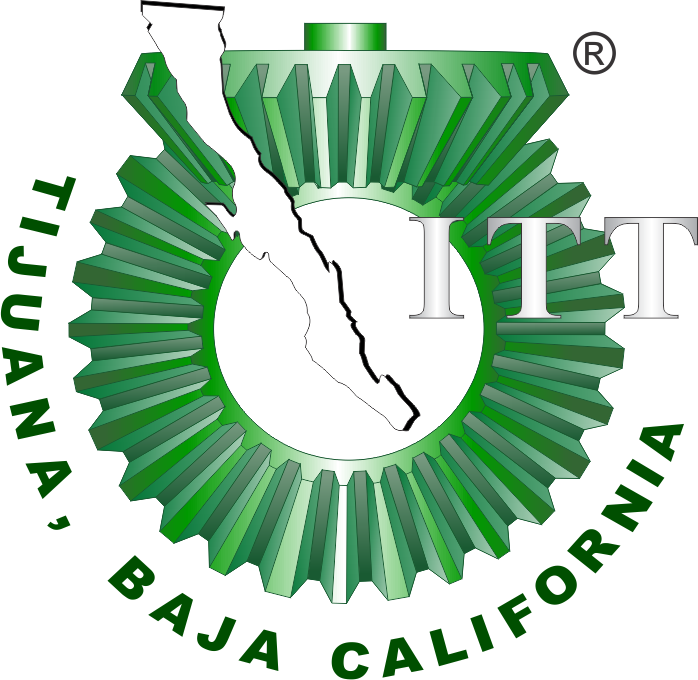

# Práctica cuatro: Modelado y control del sistema endócrino

**Departamento de Ingeniería Eléctrica y Electrónica, Ingeniería Biomédica**

**Tecnológico Nacional de México [TecNM - Tijuana], Blvd. Alberto Limón Padilla s/n, C.P. 22454, Tijuana, B.C., México**

## Información general

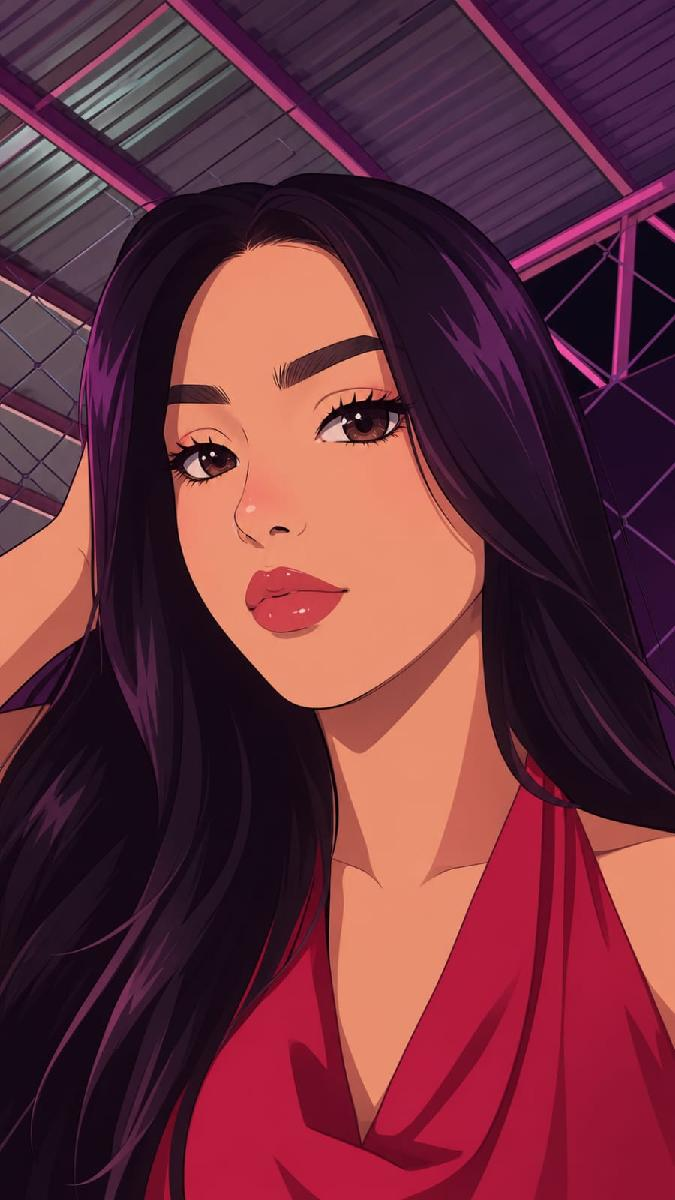

Nombre del alumno: **Castañeda Nieblas Lorena Lizel**

Número de control: **L23210695**

Correo institucional: **l23210695@tectijuana.edu.mx**

Asignatura: **Modelado de Sistemas Fisiológicos**

Docente: **Dr. Paul Antonio Valle Trujillo; paul.valle@tectijuana.edu.mx**

## Datos de la simulación

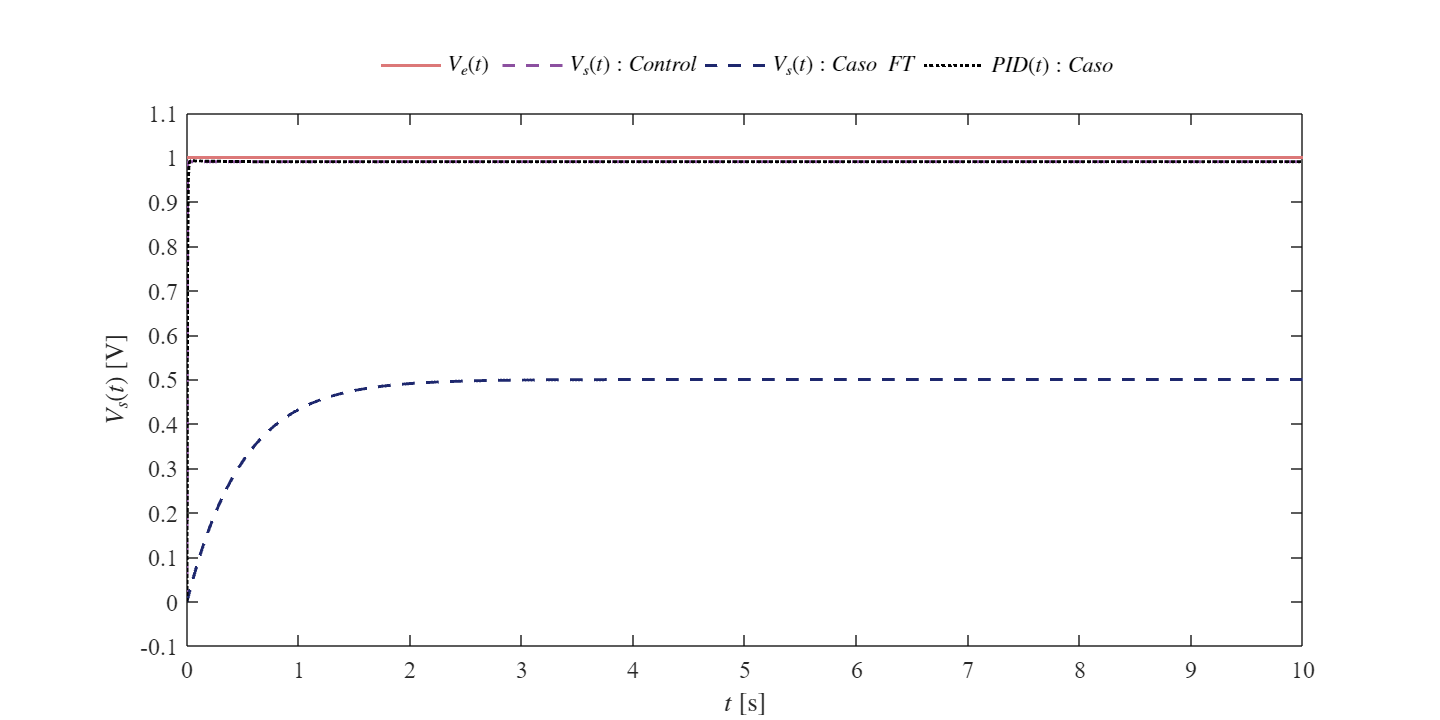

clc; clear; close all; warning('off','all')
tend = '10';
file = 'Endocrino';
open_system(file);          
parameters.StopTime = tend;            
parameters.Solver = 'ode15s';
parameters.MaxStep = '1e-4';
x = sim(file, parameters);       

plotsignals(x.tout, x.Ve, x.Vs_ctrl, x.Fsy, x.Vs_PID, 'escalon_')

## Modelo de EDOS

function Vs = endocrino(par, Ve, t)

    R1 = par(1); L = par(2); C = par(3); R2 = par(4); dt = t(2) - t(1);

    n = length(t) - 1;

    Vs = zeros(length(t), 1); Vs(1) = 0;
    Fs = zeros(length(t), 1); Fs(1) = 0;

    for i = 1:n
        Vs(i+1) = Vs(i) + ((Ve(i) - Vs(i))/(R1*C) - Fs(i)/C) * dt;
        Fs(i+1) = Fs(i) + ((Vs(i) - R2*Fs(i))/L) * dt;             
    end
end

## Respuesta a la simulación

function plotsignals(t, Ve, Vs_ctrl, Fsy, Vs_PID, signal)

    set(figure(), 'color', 'w')
    set(gcf, 'units', 'inches', 'position', [1,1,10,5])
    set(gca, 'fontname', 'times new roman', 'fontsize', 12)

    hold on; grid off; box on;

    clr1 = [220, 120, 120]/255;
    clr2 = [140, 80, 160]/255;
    clr3 = [30, 40, 110]/255;
    clr4 = [0.5, 0.5, 0.5]/255;

    order = [clr1; clr2; clr3; clr4];
    colororder(order)

    plot(t, Ve, '-', 'LineWidth', 1.5, 'Color', clr1)
    plot(t, Vs_ctrl, '--', 'LineWidth', 1.5, 'Color', clr2)
    plot(t, Fsy, '--', 'LineWidth', 1.5, 'Color', clr3)
    plot(t, Vs_PID, ':', 'LineWidth', 1.5, 'Color', clr4)

    L = legend('$V_e(t)$', '$V_s(t):Control$', '$V_s(t):Caso\ FT$', '$PID(t):Caso$');

    set(L, 'interpreter', 'latex', 'location', 'northoutside', 'orientation', 'horizontal', 'box', 'off')

    xlabel('$t$ [s]', 'interpreter', 'latex')
    ylabel('$V_s(t)$ [V]', 'interpreter', 'latex')

    xlim([0 10]); xticks(0:1:10)
    ylim([-0.1 1.1]); yticks(-0.1:0.1:1.1)

    exportgraphics(gcf, [signal, 'matlab.pdf'], 'ContentType', 'vector')

end